# Detecting Edges: Finding Road Lanes

In this script, you will experiment with various parameters to explore how they affect the detected edges. 

## 1. Effect of pre-processing

Slightly blurring an image is a useful step in edge detection algorithms. By reducing noise and minor details, the algorithm can focus on the more significant structural features of the image. However, excessive blurring can diminish important details and fine edges in the image.

Experiment with the standard deviation of the Gaussian filter using the slider control and make a note of:

- How the lane markers' visibility change.

- The amount of edges detected, particularly in the upper left (near the trees and fences).

- The thickness of the edges.

% Read in the image and convert to grayscale
img = imread("roadlanes.jpg");
img = im2gray(img);

% Apply a Gaussian blur
imgFilt = imgaussfilt(img,0.7);

% Detect edges
imgEdges = edge(imgFilt,"sobel","nothinning");

Error using imread>get_full_filename
File "roadlanes.jpg" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);

montage({img,imgFilt,imgEdges})

## 2. Effect of the edge detection algorithm

There are many edge detection algorithms. The Sobel method is a widely used algorithm. The Canny method is another popular algorithm. It is more complex, but tends to produce the smoother edges. 

Run this section to compare the two methods.

imgC = edge(imgFilt,"canny");
imgC = edge(img,"canny", [], 4.75);    
montage({imgEdges,imgC})

### Use the `threshold` input to refine the detected edges

The Canny method detects many more edges. To refine the Canny method's results,use the `threshold` input. Edges with a magnitude below the lower threshold are discarded, and edges with a magnitude above the upper threshold are preserved. If a pixel's edge strength falls between the two thresholds, it will be preserved if it is connected to a pixel that exceeds the upper threshold; otherwise, it will be discarded. Both thresholds must range between 0 and 1. Adjust the sliders to find a suitable pair of thresholds. Also note how the thresholds may change when the Gaussian blur slider (line 5) is shifted. 

imgC = edge(imgFilt,"canny",[0.25,0.5]); 
montage({imgEdges,imgC})

## 3. Different edge detection algorithm

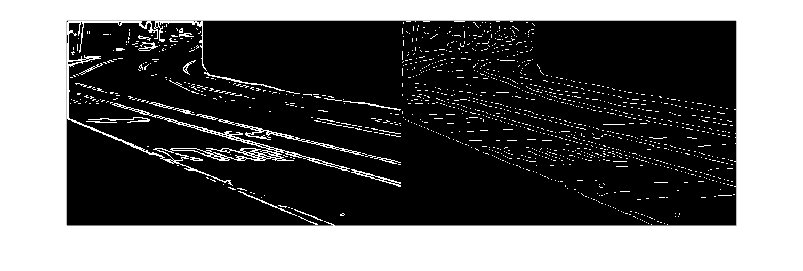

img = imread('roadlanes.jpg');
imgGray = im2gray(img);
imgFilt = imgaussfilt(imgGray, 1.25);

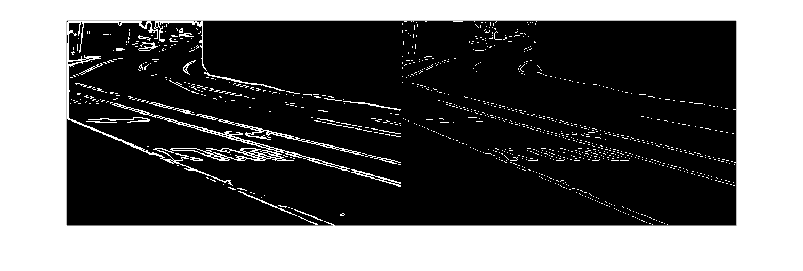


edgesSobel = edge(imgFilt, 'sobel');
edgesPrewitt = edge(imgFilt, 'prewitt');
edgesRoberts = edge(imgFilt, 'roberts');
edgesZeroCross = edge(imgFilt, 'zerocross');


montage({edgesSobel, edgesPrewitt, edgesRoberts, edgesZeroCross});

## 4. Using edges for segmentation

Edges are often used to help improve segmentation. In this example, the `imbinarize` function is used to segment the image. The mask is inverted and then Sobel edges are removed. Update the code to use the Canny edges. 

Try going back and adjusting the standard deviation of the Gaussian filter or the threshold values used for Canny edge detection. Remember to rerun the sections to see the updated results.

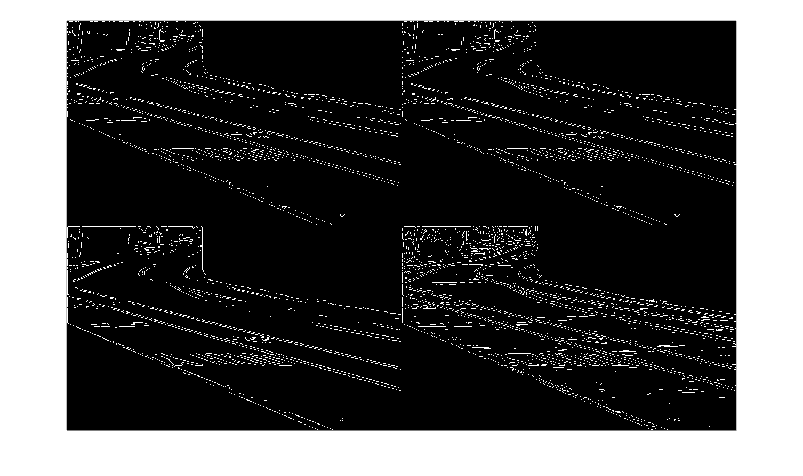

% Perform segmentation
BW = imbinarize(img);  
BW = ~BW;

% Remove edges from segmentation
newBW = BW;
newBW(imgC) = 0;

if ~ismatrix(newBW)
    newBW = newBW(:,:,1); 
end

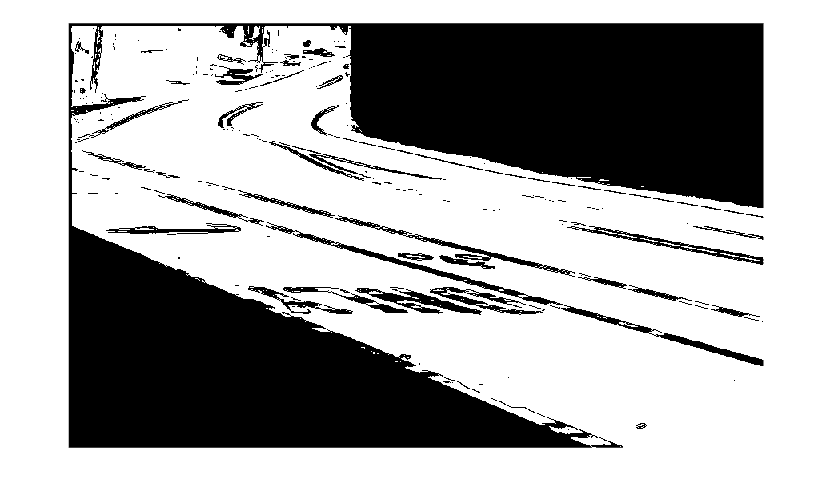


imshow(newBW)  